### Задание 3. Слежение и компенсация по выходу. 

Начальные данные для задания:

A = [12 -1 14; 
    6 0 6; 
    -6 -2 -8];
B = [11; 7; -7];
Bf = [0 2 -1 0; 
      0 0 0 0; 
      0 -2 0 0];
C = [-2 2 -1];
Cz = [2 1 3];

G = [-40 16 9 -7;
    -64 25 14 -12; 
    -26 11 7 -3; 
    48 -18 -14 8];

D = [6; -6; -4; -5]';
Dz = [-8 -2 8 -5];

w_0 = [1; 1; 1; 1];
x_0 = [0; 0; 0];

e = eig(G)

e =    0.0000 + 3.0000i
   0.0000 - 3.0000i
   0.0000 + 2.0000i
   0.0000 - 2.0000i


CD = [C D]

CD =     -2     2    -1     6    -6    -4    -5


ABfG = [A Bf; zeros(4,3) G]

ABfG =     12    -1    14     0     2    -1     0
     6     0     6     0     0     0     0
    -6    -2    -8     0    -2     0     0
     0     0     0   -40    16     9    -7
     0     0     0   -64    25    14   -12
     0     0     0   -26    11     7    -3
     0     0     0    48   -18   -14     8


rank(CD)

ans = 1

rank(ABfG)

ans = 7


l1 = 3 + 3j;
l2 = 3 - 3j;
l3 = -2;
l4 = +2j;
l5 = -2j;
l6 = +3j;
l7 = -3j;

eig(ABfG)

ans =    3.0000 + 3.0000i
   3.0000 - 3.0000i
  -2.0000 + 0.0000i
   0.0000 + 3.0000i
   0.0000 - 3.0000i
   0.0000 + 2.0000i
   0.0000 - 2.0000i



rank([ABfG - l1*eye(7,7); CD])

ans = 7

rank([ABfG - l2*eye(7,7); CD])

ans = 7

rank([ABfG - l3*eye(7,7); CD])

ans = 7

rank([ABfG - l4*eye(7,7); CD])

ans = 7

rank([ABfG - l5*eye(7,7); CD])

ans = 7

rank([ABfG - l6*eye(7,7); CD])

ans = 7

rank([ABfG - l7*eye(7,7); CD])

ans = 7

### Получаем компоненты L1,L2, K1,K2

Q = eye(7);
R = 1;
[L, ~, ~] = lqr(ABfG', CD', Q, R);
L = -L';
mat2tex(L, 2);

\begin{bmatrix}
    -133.27 \\
    -105.92 \\
    81.86 \\
    18.48 \\
    27.96 \\
    12.11 \\
    -21.25 \\
\end{bmatrix}



Lx = L(1:3)

Lx =  -133.2713
 -105.9227
   81.8627


Lw = L(4:7)

Lw =    18.4779
   27.9611
   12.1066
  -21.2466



Q = eye(3);
R = 1;
[K1,~,~] = lqr(A, B, Q, R);
K1 = -K1

K1 =     8.7057   -8.6171    8.4715


eig(A + B*K1)

ans =   -14.3859
   -3.4708
   -2.0000



mat2tex(K1, 2);

\begin{bmatrix}
    8.71 & -8.62 & 8.47 \\
\end{bmatrix}


### Рассмотрим два виртуальных выхода

### z = Cz*x + Dz*w

cvx_begin sdp;
variable P(3,4);
variable Y(1,4);

P*G - A*P == B*Y + Bf;
Cz*P + Dz == 0;
cvx_end;

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.3e-01|4.6e+03|1.2e+06| 0.000000e+00  0.000000e+00| 0:0:00| chol  2  2 
 1|1.000|0.894|2.9e-02|4.9e+02|3.0e+04| 0.000000e+00  4.935225e+03| 0:0:00| chol  1  2 
 2|1.000|0.933|3.2e-05|3.3e+01|1.2e+03| 0.000000e+00 -2.296392e+01| 0:0:00| chol  1  1 
 3|1.000|0.989|2.7e-07|3.8e-01|1.1e+01| 0.000000e+00 -2.443503e-01| 0:0:00| chol  1  1 
 4|1.000|0.98


K2 = Y - K1*P

K2 =    14.0888   -7.1421    7.4994    9.1594


mat2tex(K2, 2);

\begin{bmatrix}
    14.09 & -7.14 & 7.5 & 9.16 \\
\end{bmatrix}


out = sim('ex3.slx','ReturnWorkspaceOutputs','on');
t = out.tout;

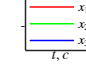

x = out.x_obsv.data';
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, x(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, x(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, x(3, :), 'b', 'LineWidth', 1.0);
title(' ')
xlabel('$t,c$','Interpreter','latex')
ylabel('$x(t)$', 'Interpreter','latex')
grid on
legend('$x_1$','$x_2$','$x_3$', ...
    'Location','best', 'Interpreter','latex')
save_file("obsv_x1")

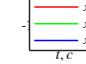

x = out.x_plant.data';
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, x(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, x(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, x(3, :), 'b', 'LineWidth', 1.0);
title(' ')
xlabel('$t,c$','Interpreter','latex')
ylabel('$x(t)$', 'Interpreter','latex')
grid on
legend('$x_1$','$x_2$','$x_3$', ...
    'Location','best', 'Interpreter','latex')
save_file("plant_x1")

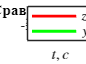

z = out.z.data;
y = out.y_plant.data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, z, 'r', 'LineWidth', 2); hold on;
plot(t, y, 'g', 'LineWidth', 2);
title('Сравнение выходов')
xlabel('$t,c$','Interpreter','latex')
ylabel('$z(t)$', 'Interpreter','latex')
grid on
legend('$z$', '$y$', ...
    'Location','best', 'Interpreter','latex')
save_file("yz1")

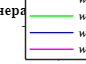

w = out.w_obsv.data';
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, w(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, w(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, w(3, :), 'b', 'LineWidth', 1.0);
hold on;
plot(t, w(4, :), 'magenta', 'LineWidth', 1.0);
title('Состояния генератора внешнего возмущения')
xlabel('$t,c$','Interpreter','latex')
ylabel('$w_f(t)$', 'Interpreter','latex')
grid on
legend('$w_1$','$w_2$','$w_3$','$w_4$', ...
    'Location','best', 'Interpreter','latex')
save_file("obsv_w1")

w = out.w_plant.data';
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, w(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, w(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, w(3, :), 'b', 'LineWidth', 1.0);
hold on;
plot(t, w(4, :), 'magenta', 'LineWidth', 1.0);
title('Состояния генератора внешнего возмущения')
xlabel('$t,c$','Interpreter','latex')
ylabel('$w_f(t)$', 'Interpreter','latex')
grid on
legend('$w_1$','$w_2$','$w_3$','$w_4$', ...
    'Location','best', 'Interpreter','latex')
save_file("plant_w1")

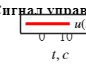

u = out.u.data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, u, 'r', 'LineWidth', 2);
title('Сигнал управления')
xlabel('$t,c$','Interpreter','latex')
ylabel('$u(t)$', 'Interpreter','latex')
grid on
legend('$u(t)$', ...
    'Location','best', 'Interpreter','latex')
save_file("u7")

**Вычислим ошибки по-компонентно**

e_w = out.w_plant.data' - out.w_obsv.data';
e_x = out.x_plant.data' - out.x_obsv.data';
e_yz = out.z.data - out.y_plant.data;

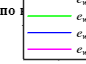

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, e_w(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, e_w(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, e_w(3, :), 'b', 'LineWidth', 1.0);
hold on;
plot(t, e_w(4, :), 'magenta', 'LineWidth', 1.0);
title('Ошибка по внешним возмущениям')
xlabel('$t,c$','Interpreter','latex')
ylabel('$e_w(t)$', 'Interpreter','latex')
grid on
legend('$e_{w1}$','$e_{w2}$','$e_{w3}$','$e_{w4}$', ...
    'Location','best', 'Interpreter','latex')
save_file("e_w1")

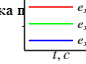

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, e_x(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, e_x(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, e_x(3, :), 'b', 'LineWidth', 1.0);
title('Ошибка по вектору состояния')
xlabel('$t,c$','Interpreter','latex')
ylabel('$e_x(t)$', 'Interpreter','latex')
grid on
legend('$e_{x1}$','$e_{x2}$','$e_{x3}$', ...
    'Location','best', 'Interpreter','latex')
save_file("e_x1")

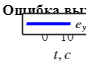

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, e_yz, 'b', 'LineWidth', 2.0);
xlabel('$t,c$','Interpreter','latex')
ylabel('$e_{y-z}(t)$', 'Interpreter','latex')
title('Ошибка выходов')
grid on
legend('$e_{y-z}$',...
    'Location','best', 'Interpreter','latex')
save_file("e_yz1")

**Собственные числа матрицы системы регулятора в форме В-С-В: **

matrix = [A+B*K1+Lx*C , B*K2 + Bf + Lx*D;
                 Lw*C ,   G + Lw*D];
eig(matrix)

ans =  -21.4553 +26.4189i
 -21.4553 -26.4189i
  -0.1016 + 2.4632i
  -0.1016 - 2.4632i
  -0.4647 + 1.4168i
  -0.4647 - 1.4168i
  -2.0719 + 0.0000i


eig(G)

ans =    0.0000 + 3.0000i
   0.0000 - 3.0000i
   0.0000 + 2.0000i
   0.0000 - 2.0000i


**Проверка, все должны быть левые корни...**

eig(A+B*K1)

ans =   -14.3859
   -3.4708
   -2.0000


eig( ([A Bf ; zeros([4 3]) G] + L*[C D]) )

ans =  -11.0293 + 0.0000i
  -3.4593 + 2.8038i
  -3.4593 - 2.8038i
  -1.7403 + 3.5581i
  -1.7403 - 3.5581i
  -0.4150 + 2.3385i
  -0.4150 - 2.3385i


### z = y

cvx_begin sdp;
variable P(3,4);
variable Y(1,4);

P*G - A*P == B*Y + Bf;
C*P + D == 0;
cvx_end;

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.2e-01|4.6e+03|1.1e+06| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  2 
 1|1.000|0.950|9.8e-03|2.3e+02|1.3e+04| 0.000000e+00  9.218775e+02| 0:0:00| chol  2  1 
 2|1.000|0.978|3.6e-05|4.9e+00|1.2e+02| 0.000000e+00  1.407817e+01| 0:0:00| chol  1  1 
 3|1.000|0.989|1.0e-06|5.6e-02|9.4e-01| 0.000000e+00  1.697204e-01| 0:0:00| chol  2  1 
 4|1.000|0.98


K2 = Y - K1*P

K2 =   -16.0031   17.3886   -4.5333    6.6221


mat2tex(K2, 2);

\begin{bmatrix}
    -16 & 17.39 & -4.53 & 6.62 \\
\end{bmatrix}


out = sim('ex3.slx','ReturnWorkspaceOutputs','on');
t = out.tout;

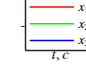

x = out.x_obsv.data';
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, x(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, x(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, x(3, :), 'b', 'LineWidth', 1.0);
title(' ')
xlabel('$t,c$','Interpreter','latex')
ylabel('$x(t)$', 'Interpreter','latex')
grid on
legend('$x_1$','$x_2$','$x_3$', ...
    'Location','best', 'Interpreter','latex')
save_file("obsv_x2")

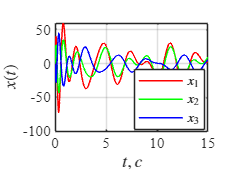

x = out.x_plant.data';
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, x(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, x(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, x(3, :), 'b', 'LineWidth', 1.0);
title(' ')
xlabel('$t,c$','Interpreter','latex')
ylabel('$x(t)$', 'Interpreter','latex')
grid on
legend('$x_1$','$x_2$','$x_3$', ...
    'Location','best', 'Interpreter','latex')
save_file("plant_x2")

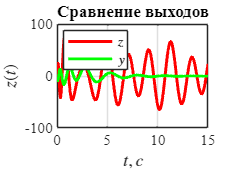

z = out.z.data;
y = out.y_plant.data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, z, 'r', 'LineWidth', 2); hold on;
plot(t, y, 'g', 'LineWidth', 2.0);
title('Сравнение выходов')
xlabel('$t,c$','Interpreter','latex')
ylabel('$z(t)$', 'Interpreter','latex')
grid on
legend('$z$', '$y$', ...
    'Location','best', 'Interpreter','latex')
save_file("yz2")

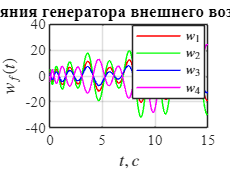

w = out.w_obsv.data';
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, w(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, w(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, w(3, :), 'b', 'LineWidth', 1.0);
hold on;
plot(t, w(4, :), 'magenta', 'LineWidth', 1.0);
title('Состояния генератора внешнего возмущения')
xlabel('$t,c$','Interpreter','latex')
ylabel('$w_f(t)$', 'Interpreter','latex')
grid on
legend('$w_1$','$w_2$','$w_3$','$w_4$', ...
    'Location','best', 'Interpreter','latex')
save_file("obsv_w2")

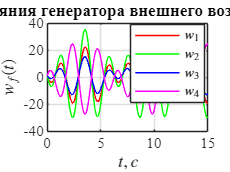

w = out.w_plant.data';
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, w(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, w(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, w(3, :), 'b', 'LineWidth', 1.0);
hold on;
plot(t, w(4, :), 'magenta', 'LineWidth', 1.0);
title('Состояния генератора внешнего возмущения')
xlabel('$t,c$','Interpreter','latex')
ylabel('$w_f(t)$', 'Interpreter','latex')
grid on
legend('$w_1$','$w_2$','$w_3$','$w_4$', ...
    'Location','best', 'Interpreter','latex')
save_file("plant_w2")

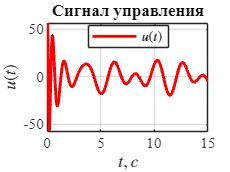

u = out.u.data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, u, 'r', 'LineWidth', 2);
title('Сигнал управления')
xlabel('$t,c$','Interpreter','latex')
ylabel('$u(t)$', 'Interpreter','latex')
grid on
legend('$u(t)$', ...
    'Location','best', 'Interpreter','latex')
save_file("u8")

Вычислим ошибки по-компонентно

e_w = out.w_plant.data' - out.w_obsv.data';
e_x = out.x_plant.data' - out.x_obsv.data';
e_yz = out.z.data - out.y_plant.data;

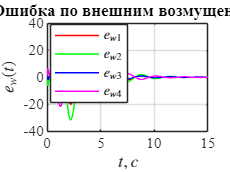

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, e_w(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, e_w(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, e_w(3, :), 'b', 'LineWidth', 1.0);
hold on;
plot(t, e_w(4, :), 'magenta', 'LineWidth', 1.0);
title('Ошибка по внешним возмущениям')
xlabel('$t,c$','Interpreter','latex')
ylabel('$e_w(t)$', 'Interpreter','latex')
grid on
legend('$e_{w1}$','$e_{w2}$','$e_{w3}$','$e_{w4}$', ...
    'Location','best', 'Interpreter','latex')
save_file("e_w2")

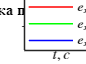

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, e_x(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, e_x(2, :), 'g', 'LineWidth', 1.0);
hold on;
plot(t, e_x(3, :), 'b', 'LineWidth', 1.0);
title('Ошибка по вектору состояния')
xlabel('$t,c$','Interpreter','latex')
ylabel('$e_x(t)$', 'Interpreter','latex')
grid on
legend('$e_{x1}$','$e_{x2}$','$e_{x3}$', ...
    'Location','best', 'Interpreter','latex')
save_file("e_x2")

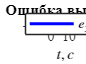

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, e_yz, 'b', 'LineWidth', 2.0);
xlabel('$t,c$','Interpreter','latex')
ylabel('$e_{y-z}(t)$', 'Interpreter','latex')
grid on
title('Ошибка выходов')
legend('$e_{y-z}$',...
    'Location','best', 'Interpreter','latex')
save_file("e_yz2")

**Собственные числа матрицы системы регулятора в форме В-С-В: **

matrix = [A+B*K1+Lx*C , B*K2 + Bf + Lx*D;
                 Lw*C ,   G + Lw*D];
eig(matrix)

ans =  -22.0440 +27.5032i
 -22.0440 -27.5032i
   0.0000 + 3.0000i
   0.0000 - 3.0000i
   0.0000 + 2.0000i
   0.0000 - 2.0000i
  -2.0271 + 0.0000i


eig(G)

ans =    0.0000 + 3.0000i
   0.0000 - 3.0000i
   0.0000 + 2.0000i
   0.0000 - 2.0000i


**Проверка, все должны быть левые корни...**

eig(A+B*K1)

ans =   -14.3859
   -3.4708
   -2.0000


eig( ([A Bf ; zeros([4 3]) G] + L*[C D]) )

ans =  -11.0293 + 0.0000i
  -3.4593 + 2.8038i
  -3.4593 - 2.8038i
  -1.7403 + 3.5581i
  -1.7403 - 3.5581i
  -0.4150 + 2.3385i
  -0.4150 - 2.3385i


**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab12\latex12\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');
end